# Restricted Three Body Problem

(Created on 21 Feb 2020 18:45)

## Dependencies of the program

### Explicit and Implicit

- See MAIN_LyapOrbit.m file

## References for the Program

- W S koon ,MW Lo, JE Marsden, SD Ross - Dynamical Systems, the Three Body Problem and Space Mission Design (For the Lyapunoc orbits continuation Methods).

- Daniel J Grebow - Generating Periodic Orbits in the circular Restricted Three Body Problem With Applications to Lunar South Pole Coverage - MS Thesis (2006)(Insights for differential Correction andcontinuation Halo orbits)

- Srianish Vutukuri - Spacecraft Trajectory Design Techniques using Resonant Orbits (for DC and continuation)

- Thomas Pavlak - Mission Design In the Earth Moon System Transfer Trajectories and station keeping

- TM Vaquero Escribano - Poincare Sections and resonant orbits in the Restricted Three Body Problem.

## MAIN CODE

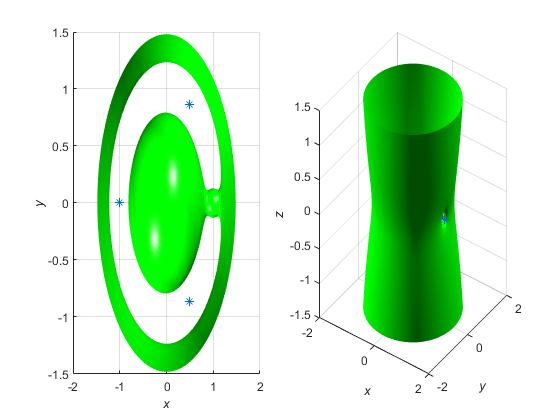

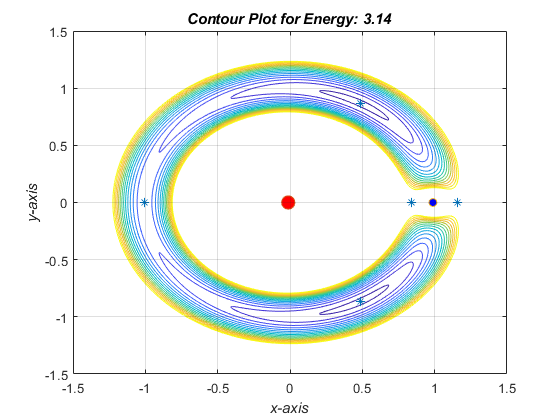

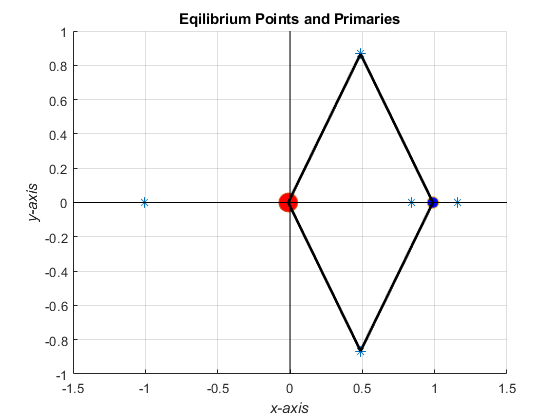

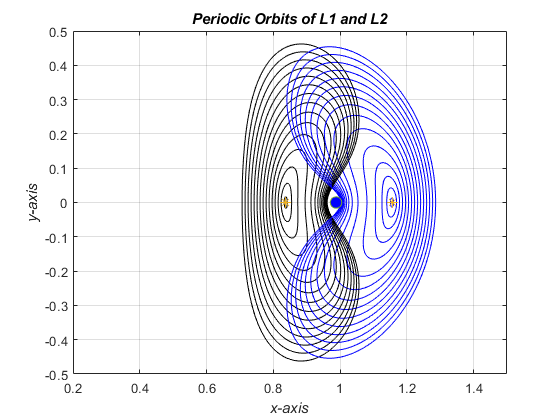

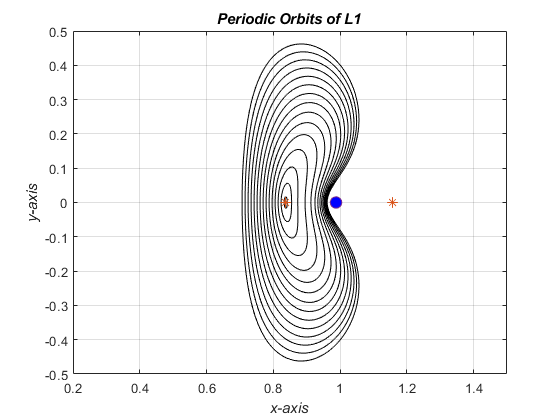

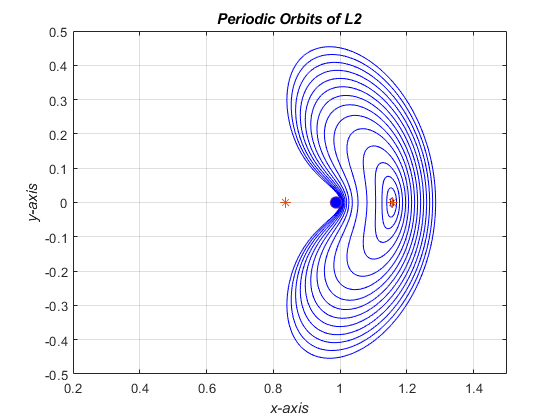


clearvars;clc;close all

### Get the UserData


% The program can handle both 2 and 3 dimension
% Choose the dimension of the problem(3 or 2)
UserDat.Dimension      = 3;% input('Give the problem dimension: ');
% Input the Primary/Secondary
% See the description above before entering Primary and Secondary
UserDat.Primary        = 'earth';%input('Enter the primary body (string input):');
UserDat.Secondary      = 'moon';%input('Enter the secondary body (string input):');

% Input for how many equilibrium points you want the data for ?(Max 3-
% L1,L2,L3)
UserDat.PointLoc       = 2;%input('For how many  equilibrium points do you want orbit parameters? :');
% Enter the number of families
UserDat.NoofFam        = 30;%input('Enter No of Lyapunov orbit families:');
% Check if you want to see correction plot(Enter 0 or 1).
UserDat.CorrectionPlot = 0;%input('Do You want to see correction plot of differential correction?:');

tic

### Get the GlobalData

G_var                  = GlobalData(UserDat.Primary,UserDat.Secondary);
fprintf('mu value %f\n',G_var.Constants.mu)


### Perform Differential Correction and Continuation and get all the orbit parameters

% Only user data and global variables are required to continue.
[LyapOrb]              = LyapOrbitParameters(UserDat,G_var);
%toc - takes approx 89 secs

### Save all the parameters in .mat file

fprintf('\n\n')
fprintf('Saving the data...\n')
fprintf('\n')
save LyapOrbPar LyapOrb % used for plotting (Using the saved file saves time)
                 

## Plot Section

% Note this "Plotter" uses the saved data internally so that one need not run every time to get
% the plot 
Plotter(G_var)
toc
% takes 21.493200 seconds for earth moon system(for 30- orbits) with i7 - 4 core and 16g Ram ,without
% parallel pool.






# Log

- Till Lyapuniv Orbits parameters and all the plots fully completed on 9 march 2020(Start date was 20 Feb 2020).

- Equilibrium point manifolds(10 March 2020)